clc; clear;
%1-1 convert to gray
baby = imread('baby.jpg');
temp = imread("template.jpg");
baby_gray = rgb2gray(baby);
temp_gray = rgb2gray(temp);

%1-2 HOG feature extraction
baby_Hog = extractHOG(baby_gray);
temp_Hog = extractHOG(temp_gray);

%2-1 Template Matching
BestLocation = findBestMatch(baby_Hog,temp_Hog);

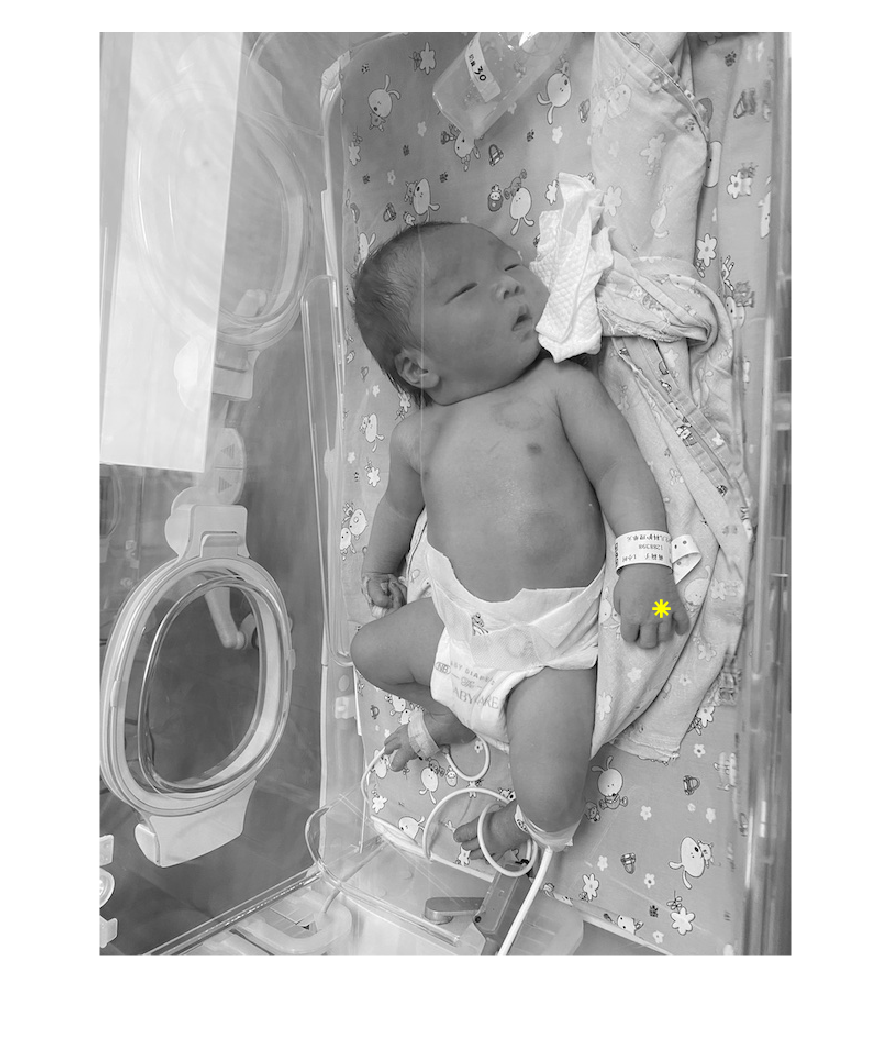

%2-2 Mark the Best Matching Location
Size_temp = size(temp_gray);
%转换坐标
pointCenter = (BestLocation*8) + ([Size_temp(1), Size_temp(2)]/2);
%visual
imshow(baby_gray)
hold on
plot(pointCenter(2), pointCenter(1), 'y', 'MarkerSize',10, 'LineWidth',1.5, 'Marker','*');
hold off

function  HOGfearure = extractHOG(img)
%1-2-1 sobel filter
sobelx = [-1 0 1; -2 0 2; -1 0 1];
sobely = [1 2 1; 0 0 0; -1 -2 -1];
dx = conv2(img, sobelx, 'same');
dy = conv2(img, sobely, 'same');
Gmag = sqrt(dx.^2 + dy.^2);
Gdir = atan2d(dy, dx);
Gdir(Gdir < 0) = Gdir(Gdir < 0) + 180;
Gdir(Gdir == 180) = Gdir(Gdir == 180) - 0.00001;
%1-2-2 Dividing the image into cells of 8x8 pixels each.
%1-2-3 gradient orientation histogram
cellsize = 8;
numBins = 9;
binRange = 180 / numBins;
[rows,cols] = size(img);

for i =1:floor(rows / cellsize)
    for j = 1:floor(cols / cellsize)
    Cellmag = Gmag((i-1)*cellsize+1:i*cellsize, (j-1)*cellsize+1:j*cellsize);
    Celldir = Gdir((i-1)*cellsize+1:i*cellsize, (j-1)*cellsize+1:j*cellsize);
    goh = zeros(1,9);
     for w = 1:numel(Cellmag)
     bin = floor(Celldir/binRange) +1;
         if bin == 0
         bin=1;
         elseif bin>(180/binRange)
         bin = 180/binRange;
         end
         goh(bin) = goh(bin)+Cellmag(w);
     end
     GOH(i, j, :) = goh;
    end
end
for i = 1:floor(rows / cellsize)-1
 for j = 1:floor(cols / cellsize)-1
 tempblock = GOH(i : i+1, j : j+1, :);
 HOGfearure(i,j,:) = reshape(tempblock, 1, []);
 end
end
end

function BestLocation = findBestMatch(hog1,hog2)
cellsize = 8;
T_Features = reshape(hog2,1,[]);
min_diff = inf;
[rows, cols, ~] = size(hog1);
%%L2 norm
for i = 1:(rows-size(hog2, 1)+1)
 for j = 1:(cols-size(hog2, 2)+1)
 baby_Features = reshape(hog1(i:i+size(hog2, 1)-1, j:j+size(hog2, 2)-1, :), 1,[]);
 tempDiff = normest(baby_Features-T_Features);
 if tempDiff < min_diff
 min_diff = tempDiff;
 BestLocation = [i,j];
 end
 end
end
end